clc, clear all;

%Regression, Interpolation
function [coef, r_square] = polyreg(x, y, n)
    A = zeros(n+1);
    b = zeros(n+1,1);
    x = x(:);
    y = y(:);
    for i = 1:n+1
        b(i) = (sum((x.^(i-1)).*y));
        for j = 1:n+1 
            A(i,j) = sum(x.^(i+j-2));
        end
    end

    coef = A\b;

    St = sum((y-mean(y)).^2);
    poly_fit = 0 ;
    for i = 1:length(coef) 
        poly_fit = poly_fit + coef(i)*x.^(i-1);

    Sr = sum((y-poly_fit).^2);

    r_square = sqrt((St-Sr)/St);
    end
end
y = [2.1; 7.7; 13.6; 27.2; 40.9; 61.1];
x = 0:5;
[coef, r_sqaure] = polyreg(x, y, 2);

disp(coef);

    2.4786
    2.3593
    1.8607



disp(r_sqaure);

    0.9993



function f = lagint(xs, fs, x) 
    f = 0;
    for i  = 1:length(xs)
        xi = xs(i);
        fi = fs(i);
        Li = 1;
        for xj = xs
           if xj ~= xi
            Li = Li*(x-xj)/(xi-xj);
           end   
        end
        f = f + Li*fi;
    end
end

xs = [1,3,4,5,6];
fs = log(xs);

flg = lagint(xs, fs, 2);

disp(flg)

    0.6757



x = 1:0.1:10

x =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


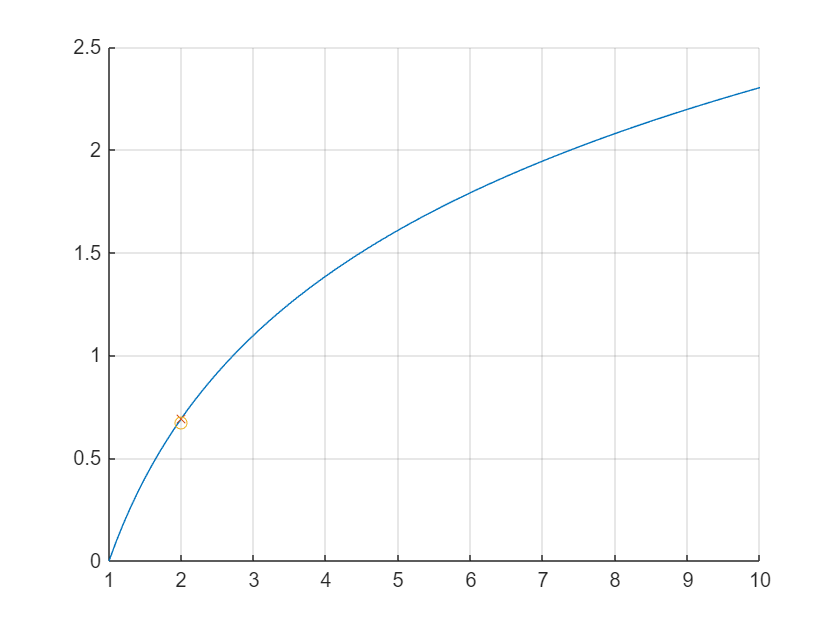


figure;
hold on;
plot(x, log(x));
scatter(2, log(2), "x")
scatter(2,flg);
grid(true);
hold off;